# Read File One Line at a Time

Read a single line from a file, first excluding newline characters, and then including them. Use the following file. 

 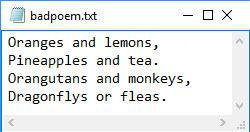

To read the first line from the file `badpoem.txt`, use `fopen` to open the file. Then read the first line using `fgetl`, which excludes the newline character.

fid = fopen('badpoem.txt');
line_ex = fgetl(fid)  % read line excluding newline character

To reread the same line from the file, first reset the read position indicator back to the beginning of the file.

frewind(fid);

Use the fgets function to read the first line from the file `badpoem.txt`, which reads the line including the newline character. 

line_in = fgets(fid) % read line including newline character

Compare the output by examining the lengths of the lines returned by the `fgetl` and `fgets `functions.

length(line_ex)
length(line_in)

`fgetl` returns an output that displays in one line, while `fgets` returns an output that includes the newline character and, therefore, displays it in two lines. 

line_ex
line_in 

Close the file.

fclose(fid);

*Copyright 2012 The MathWorks, Inc.*